option_price = .75;
num_options = 100;
option_strike_price = 12.5; % These are put options

stock_price = 11.83;
num_stocks = 78;

stock_price_mesh = 11:.01:13;

option_return = max(option_strike_price-stock_price_mesh,0)-option_price;
stock_return = stock_price_mesh-stock_price;

total_return = num_options*option_return+num_stocks*stock_return;
for index = 2:length(total_return)
    if total_return(index-1)*total_return(index) < 0
        disp(stock_price_mesh(index))
    end
end

   11.4700

   12.8000



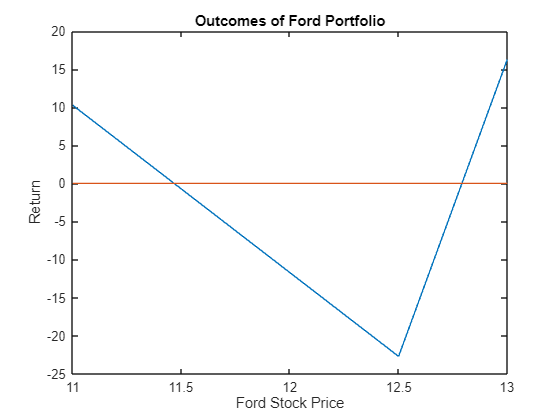



plot(stock_price_mesh,num_options*option_return+num_stocks*stock_return)
hold on
plot([11 13],[0 0])
xlabel('Ford Stock Price')
ylabel('Return')
title('Outcomes of Ford Portfolio')